# Linear OLS Estimation

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## Estimation without an Intercept

Fit a line from the origin through two points, given Equations $Y=a\cdot X$, where we have two pairs of points for x and y.

rng(3);
[x1, x2] = deal(rand(),rand());
[y1, y2] = deal(rand(),rand());
ar_x = [x1,x2]';
ar_y = [y1,y2]';

Fit a line through the two points, passing through the x-intercept. Three formulas that provide the same answer.

% simple formula
fl_slope_basic = (1/(x1*x1 + x2*x2))*(x1*y1 + x2*y2);
% (X'X)^(-1)(X'Y)
fl_slope_matrix = inv(ar_x'*ar_x)*(ar_x'*ar_y);
% Use matlab function
tb_slope_fitlm = fitlm(ar_x, ar_y, 'Intercept',false);
fl_slope_fitlm = tb_slope_fitlm.Coefficients{1, 1};

Visualize results.

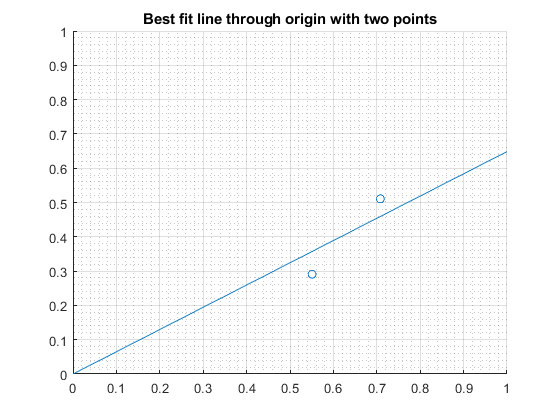

figure();
hold on;
scatter([x1,x2], [y1,y2]);
xlim([0, 1]);
ylim([0, 1]);
refline(fl_slope_basic, 0);
grid on;
grid minor;
title('Best fit line through origin with two points');